# Lab 2: MATLAB Unit Conversions

Created: 16 July 2018

By: Samuel Bechara, PhD

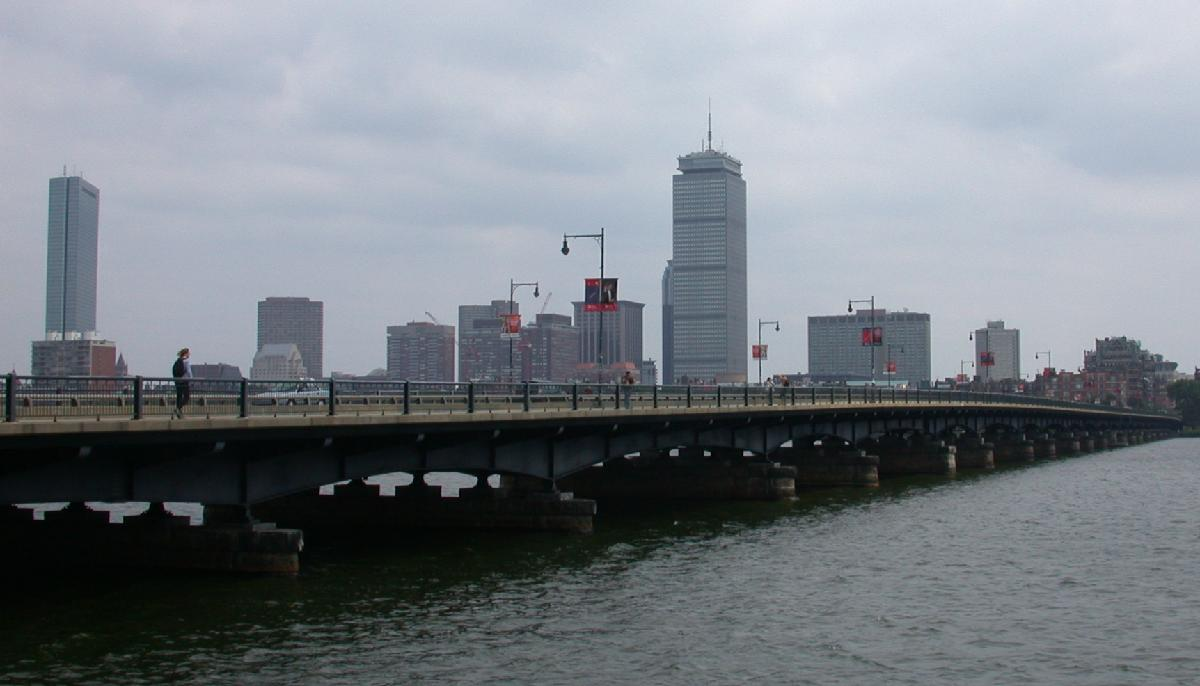

*Figure 2.1: The harvard bridge, 364.4 smoots + 1 ear long*

## Introduction

In this lab we will be creatng a MATLAB script file that allows the user to perform several different conversions. Specifially the script file will allow the user to choose to convert between: 

- specific measurements from United States customary units (USCU) to metric units and vice-versa

- dimensions within the same measurement system

- silly units to metric units and vice-versa

## Key Concepts and Takeaways

Remember, you have a lot of time to work on and finish this lab. It is important that you really nail down these concepts and are comfortable with them as we will continually use these concepts throughout the semester. Take as much time as you need to really learn what these things do!

**Review from Last Lab - You REALLY need to get this stuff down this week if it is a bit shaky**

- MATLAB commands: `clear, clc`

- MATLAB Variables

- MATLAB Math Operations (addition, subtraction, etc)

**New Stuff**

- The MATLAB `input()` function

- The MATLAB `disp()` function vs `fprintf()` function

- MATLAB Sections using `%%`

- The importance of commenting your scripts

- Where to find help when you are stuck

**DISCLAIMER**: This is only our second MATLAB lab and likely your first time writing a real *program* in MATLAB (exciting stuff! I love MATLAB and hope you will learn to love it too!). Remember, learning is an active process and as such, you need to type out all the commands on your own. It is ok to work together but you should *never copy and paste!* Banging out on the keyboard is part of the learning process.

## Commenting - `%`

Comments in MATLAB scripts are simply lines of code that are ignored by MATLAB. They are intended for both the programmer, so they can remember what they were doing / attempting and for the user, to give them hints and tips. Comments in MATLAB are denoted with a `%` and run until the end of the line. That means you can do both whole line or inline comments. MATLAB automagically makes comments green as an easy indicator to the user / programmer. 

For example:

% Calculate Force using Hooke's Law (this is a whole line comment)
% Hookes Law: F = kx
k = 190; % k is the spring constant (this is an inline comment, the k = 190 will be evaluated but the comment will not)
x = 20; % recall, x has units of meters
F = k*x

F = 3800

Writing good comments for your programs and scripts may seem like a waste of time. Afterall, YOU know what you are doing so why do you need to write it down? Well, take a look at the following lines of code (borrowed from MECH 105) and see if you can decipher what they do.

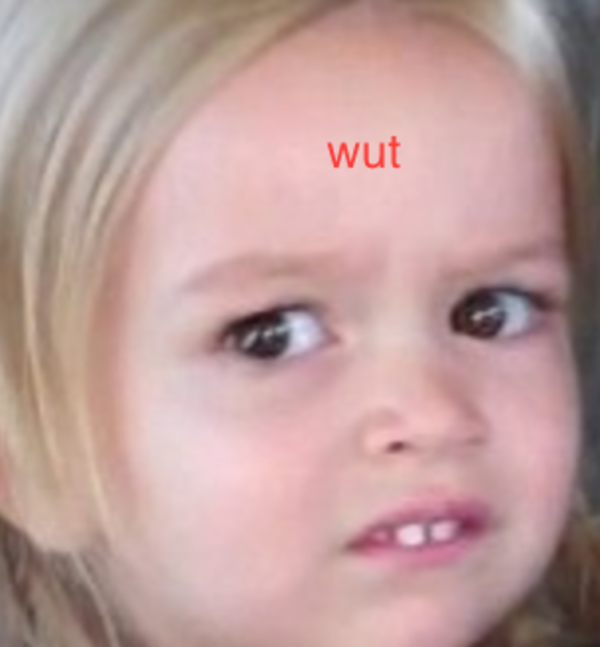

*Figure 2.2: You after looking at that code.*

It is true that you don't really have enough background to understand what those commands do. But even if you did understand the commands, it is still unclear what they do and what they are for. Now look at the same bit of code, but this time with some comments.

See the difference? Now you can at least get an idea of what those lines of code do. **The comments make it so that it is CLEAR what the code does**. Comments are very important for making your code legible and decipherable. In fact, if you ask the TAs or myself for help on the code, and you do not have comments, we will refuse to help you. It is too difficult to know what you were trying to do. So use comments!

##     Commented Headers

Commented headers are a great tool to ensure that you always know WHAT your script does and how it works at a quick glance. Take a look at the header for another MECH 105 homework problem:

This header gives you all of the information you need to understand what that script does. It is clear what the script is titled (`homework2_2-solution.m`) who made it, when, who modified it, and what information it is trying to convey. This header lives at the very top of every script file that I write (with the details changed accordingly, duh). **From now on, in order to recieve full credit, all of the script files that you turn in must include a similar comment header. **You can get fancy, customize it however you like, but this is the bare minimum necessary.

## Sections - `%%`

Sections in MATLAB scripts are ways that you can divide your script up into seperate chunks that **can be run independently**. If you pay attentioned last week, you noticed that there was a button that says "Run Section" in the "Editor" tab of the MATLAB banner. Remember, the editor tab is only visible when you have a script open!

*Figure 2.3: The "Run" area of the "Editor" tab on the MATLAB Banner*

When you create sections in your scripts by using two comment symbols, `%%`, MATLAB allows you to run only the code in that specific section. This is great for debugging and making user friendly scripts! MATLAB indicates which section is currently selected by highlighting the background in a yellow-ish color.

Go ahead and take a peek at this week's lab deliverables. I'll wait...

Notice how the first requirement states that you must have your conversions in different sections? When we are grading your assignment, we are going to run each section of your code for the appropriate conversions. Since you need a section to convert from feet to meters, you will also need another section to convert from meters to feet, etc.

Here is a template that you can use to help you get started with sections:

## Getting `input()` from a User

In order to make a script that is actually interesting, it would be nice to get some input from the user. For example. if we are converting from feet to meters, it would be useful to ask the user what number of feet they are looking to convert! Well MATLAB makes this super easy for us by supplying a built-in function called `input()`. How do you use the function? Well, I won't always be there for you so now is a good time to figure out how to use the MATLAB help functionality. Go ahead and try evaluating the following in the MATLAB command window.

help input

 input  Prompt for user input. 
    RESULT = input(PROMPT) displays the PROMPT string on the screen, waits
    for input from the keyboard, evaluates any expressions in the input,
    and returns the value in RESULT. To evaluate expressions, input accesses
    variables in the current workspace. If you press the return key without
    entering anything, input returns an empty matrix.
 
    STR = input(PROMPT,'s') returns the entered text as a MATLAB string,
    without evaluating expressions.
 
    To create a prompt that spans several lines, use '\n' to indicate each
    new line. To include a backslash ('\') in the prompt, use '\\'.
 
    Example:
 
       reply = input('Do you want more? Y/N [Y]:','s');
       if isempty(reply)
          reply = 'Y';
       end
 
    See also keyboard.

    Reference page for input



So to get help on MATLAB built-in functions, all you have to do is type `help function_name`. The other option is Google. Be careful with googling answers though, while it is a powerful tool, it can lead to some bad practices. Google sparingly.

Anyways, back to the input. What MATLAB is telling you is that in order to get input from a user you create a variable (called `reply` in the example MATLAB give) which will be assigned the output of the `input()` function. Note, you do not and SHOULD not put the 's' option as noted in the MATLAB example. We want our user to input numbers, not strings.

Here is a better example of what you should have:

feet = input('Please input the number of feet to convert: ');

This will store whatever number the user types in the command window in the variable `feet`. You can then use the variable `feet` for your conversions.

## Outputting to a User

As you learned in your reading, there are two main methods to output text to the user of your program; `disp()` and `fprintf()`. Your text (specifically Chatper 17.2) has good descriptions of how to use these two functions. I suggest that you use your text or the MATLAB help as a reference to ensure that you use the correct one in your script. *The requirements are specific so that you can use only one*. If you don't remember which one you need to use, take some time to flip through Chapter 17.2 in your book to investigate. It is up to you to figure out which to use! There is only one correct answer. Take some time to play around with both and get a feel for how they work.

## Conversions

Whew, we are almost ready to start. At this point, you should have an idea to how this puzzle fits together.

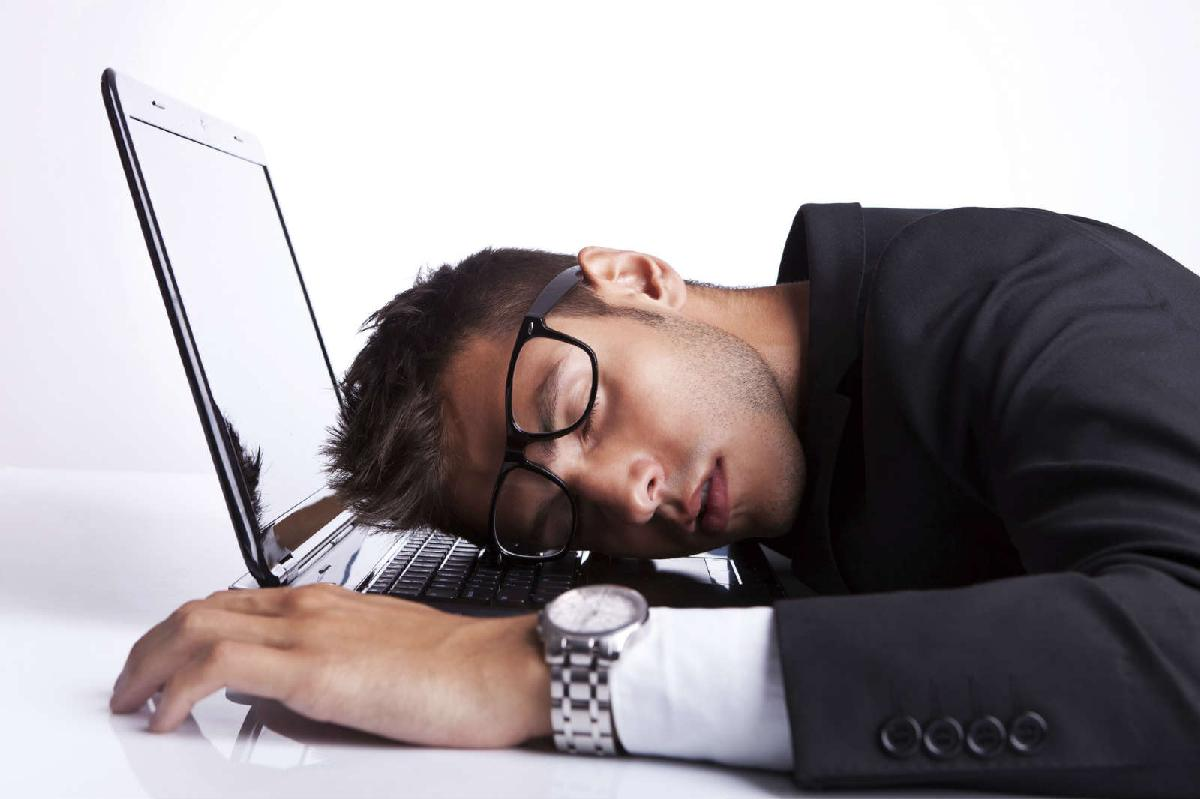

*Figure 2.4: Totally not you after getting to this point!*

My last little hint to you is to create a conversion factor for each of your sections to use.

For example: lets say that we are converting from inches to millimeters. A quick google search shows: $1 in = 25.4mm$. That means when we convert 10 inches to millimeters we are doing:


$${10in*{{25.4mm}\over{1in}}}={254mm$$


In this case our conversion factor is ${25.4}{{mm}\over{in}}$. I highly encourage you to setup the problem in MATLAB like this:

This makes it easy for us to read, and easy to see where you went wrong if you need help!

## Lab Deliverable -  Conversion Script

**Script Requirements**

- You are only turning in ONE script for this lab. **Each conversion must be in it's own seperate section using **`%%`

- Your script must be named `"lastname_firstname_lab2.m"`, where l`astname` is replaced by your actual last name...duh. Ok I am going to stop saying that from now on and assume you get it.

- The script must include a commented header that includes: the name of the script file, the date, the name of the author. See `script_template.m` for a hint.

- Each section must start with a description of the section i.e.) what conversion it is doing. Be specific, concise, and clear so your user can follow along!

- Variables must have names that make sense. Good variable name -> `meter`  Bad variable name -> `m`

- The` input() `description must be specific to the conversion taking place. I.E. "`Please enter the number of feet to convert to meters: `"

- The output must include a description of the conversion. I.E. "`You entered 6 feet. That is equal to 1.83 meters`"

- The input and output must be truncated to two decimal places when displayed to the user.

**    You must include the following three conversions. The **`<-->`** indicates converting back and forth (each bullet point will need 2 sections):**

- Feet `<-->` Meters

- Meters per Second `<-->` Kilometers per Hour

- **ANY ONE UNIT ON THIS LIST **[https://en.wikipedia.org/wiki/List_of_humorous_units_of_measurement](https://en.wikipedia.org/wiki/List_of_humorous_units_of_measurement) `<-->` Whatever makes sense

## Example Solution Output

To help you, I have included a screenshot of what is outputted to the command window after successfully running a section of the solution script.

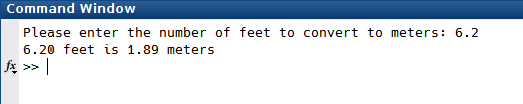

*Figure 2.5: Example showing the Command Window ouput of a successful run of the program.*